# Dinamica Veicolo Autobilanciato - gruppo Calegari

### Setup iniziale

clear
clc
digits(4)

### Definizione delle variabili simboliche

syms t; % tempo
syms T; % Energia cinetica del sistema
syms U; % Energia potenziale del sistema
syms alpha; % Angolo di offset (inclinazione utente) che sposta in avanti il baricentro
syms beta; % Angolo baricentro asta

syms q_1 q_1_p q_2 q_2_p; % Coordinate libere
syms phi(t); % posizione carrello/r
vel = diff(phi, t); %velocità carello/r
syms theta(t); % angolo inclinazione
vel_ang = diff(theta, t);%vel angolare
syms b; % Attrito viscoso
syms F; % Forza esterna (TODO)

### Definizione masse e gravità

% Massa singola ruota
m_r = sym('3');
% Massa asta
m_a = sym('3.5');
% Massa uomo (da far variare poi)
m_c = sym('70');

% Massa carello(base) + batterie
%suppongo le batterie all'interno
m_b = sym('20');

% Massa totale del sistema
M = m_a+m_b+m_c+2*m_r;

% Costante gravitazionale
g = sym('9.81');

### Definizione delle altezze [m]

% Altezza asta
h_a = sym('1.4');

% Altezza base
h_b = sym('0.2');

% Profondità base
w_b = sym('0.5');

% Posizione baricentro base (valore assoluto)
z_b = sym('0.1');

% Posizione baricentro corpo umano
h_c = sym('1.70'); % Altezza uomo

% Raggio ruota
r = sym('0.22');

### Definizione inerzie

% Inerzia asta
J_a = sym('0.1669');

% Inerzia della base
J_b = sym('0.6667');

% Inerzia del corpo (TODO: lungo asse z????)
J_c = (1732353*h_c + 619298*2.20462*m_c - 277625773)*10e-7;

% Inerzia della singola ruota
J_r = sym('0.1452');

### Definizione delle costanti geometriche a e beta (come in immagine che si trova in una codnizione di **θ = 0**)

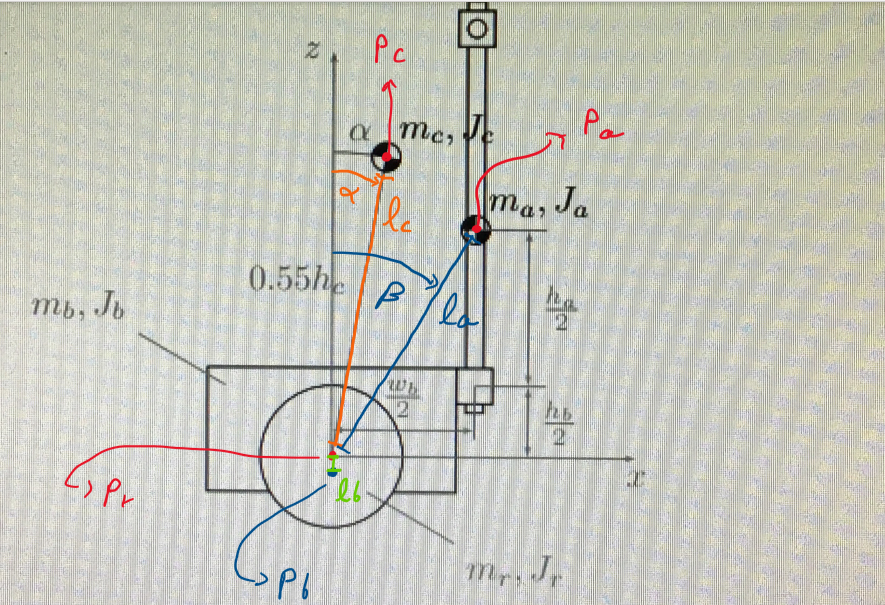

temp_1 = (h_a / 2) + (h_b / 2);
temp_2 = w_b / 2;

l_c = 0.55 * h_c

$$l\_c = 0.935$$

l_b = 0.1

l_b = 0.1000

l_a = sqrt((temp_1)^2 + (temp_2)^2)

$$l\_a = 0.8382$$


alpha = 0;
beta = atan(temp_2/temp_1)

$$beta = 0.3029$$

### Definisco il problema per il punto Pa

P_a = [phi*r+l_a*sin(theta+beta); l_a*cos(theta+beta); theta]

$$P\_a(t) = \left(\begin{array}{c} 0.8382\,\sin\left(\theta \left(t\right)+0.3029\right)+0.22\,\varphi \left(t\right)\\ 0.8382\,\cos\left(\theta \left(t\right)+0.3029\right)\\ \theta \left(t\right) \end{array}\right)$$

V_a = diff(P_a, t)

$$V\_a(t) = \left(\begin{array}{c} 0.8382\,\cos\left(\theta \left(t\right)+0.3029\right)\,\frac{\partial }{\partial t}\theta \left(t\right)+0.22\,\frac{\partial }{\partial t}\varphi \left(t\right)\\ -0.8382\,\sin\left(\theta \left(t\right)+0.3029\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\\ \frac{\partial }{\partial t}\theta \left(t\right) \end{array}\right)$$

M_a = [m_a,0,0; 0,m_a,0; 0,0,J_a] % Matrice delle masse/inerzie

$$M\_a = \left(\begin{array}{ccc} 3.5 & 0 & 0\\ 0 & 3.5 & 0\\ 0 & 0 & 0.1669 \end{array}\right)$$

T_a = 1/2 * transpose(V_a) * M_a * V_a;
U_a = m_a * g * l_a * cos(theta+beta);
L_a = T_a - U_a

$$L\_a(t) = \begin{array}{l} 0.08345\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}-28.78\,\sigma_{1}+\left(1.467\,\sigma_{1}\,\frac{\partial }{\partial t}\theta \left(t\right)+0.385\,\frac{\partial }{\partial t}\varphi \left(t\right)\right)\,\left(0.8382\,\sigma_{1}\,\frac{\partial }{\partial t}\theta \left(t\right)+0.22\,\frac{\partial }{\partial t}\varphi \left(t\right)\right)+1.229\,{\sin\left(\theta \left(t\right)+0.3029\right)}^{2}\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta \left(t\right)+0.3029\right) \end{array}$$

### Definisco il problema per il punto Pc (utente)

P_c = [phi*r+l_c*sin(theta+alpha); l_c*cos(theta+alpha); theta + alpha]

$$P\_c(t) = \left(\begin{array}{c} 0.935\,\sin\left(\theta \left(t\right)\right)+0.22\,\varphi \left(t\right)\\ 0.935\,\cos\left(\theta \left(t\right)\right)\\ \theta \left(t\right) \end{array}\right)$$

V_c = diff(P_c,t)

$$V\_c(t) = \left(\begin{array}{c} 0.935\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)+0.22\,\frac{\partial }{\partial t}\varphi \left(t\right)\\ -0.935\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\\ \frac{\partial }{\partial t}\theta \left(t\right) \end{array}\right)$$

M_c = [m_c,0,0; 0,m_c,0; 0,0,J_c]

$$M\_c = \left(\begin{array}{ccc} 70 & 0 & 0\\ 0 & 70 & 0\\ 0 & 0 & -179.1 \end{array}\right)$$

T_c = 1/2 * transpose(V_c) * M_c * V_c;
U_c = m_c * g * l_c * cos(alpha+theta);
L_c = T_c - U_c

$$L\_c(t) = 30.6\,{\sin\left(\theta \left(t\right)\right)}^{2}\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}-89.55\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}-642.1\,\cos\left(\theta \left(t\right)\right)+\left(32.73\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)+7.7\,\frac{\partial }{\partial t}\varphi \left(t\right)\right)\,\left(0.935\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)+0.22\,\frac{\partial }{\partial t}\varphi \left(t\right)\right)$$

### Definisco il problema per il punto Pb (base)

P_b = [phi*r+l_b*sin(pi+theta); l_b*cos(pi+theta); pi+theta]

$$P\_b(t) = \left(\begin{array}{c} 0.22\,\varphi \left(t\right)-\frac{\sin\left(\theta \left(t\right)\right)}{10}\\ -\frac{\cos\left(\theta \left(t\right)\right)}{10}\\ \pi +\theta \left(t\right) \end{array}\right)$$

V_b = diff(P_b,t)

$$V\_b(t) = \left(\begin{array}{c} 0.22\,\frac{\partial }{\partial t}\varphi \left(t\right)-\frac{\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)}{10}\\ \frac{\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)}{10}\\ \frac{\partial }{\partial t}\theta \left(t\right) \end{array}\right)$$

M_b = [m_b,0,0; 0,m_b,0; 0,0,J_b]

$$M\_b = \left(\begin{array}{ccc} 20 & 0 & 0\\ 0 & 20 & 0\\ 0 & 0 & 0.6667 \end{array}\right)$$

T_b = 1/2 * transpose(V_b) * M_b * V_b;
U_b = m_b * g * l_b * cos(pi+theta);
L_b = T_b - U_b

$$L\_b(t) = \begin{array}{l} 19.62\,\cos\left(\theta \left(t\right)\right)+0.3333\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}+\frac{{\sin\left(\theta \left(t\right)\right)}^{2}\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{10}+\left(\sigma_{1}-2.2\,\frac{\partial }{\partial t}\varphi \left(t\right)\right)\,\left(\frac{\sigma_{1}}{10}-0.22\,\frac{\partial }{\partial t}\varphi \left(t\right)\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right) \end{array}$$

### Definisco il problema per il punto Pr (ruota)

P_r = [phi*r; 0; phi]

$$P\_r(t) = \left(\begin{array}{c} 0.22\,\varphi \left(t\right)\\ 0\\ \varphi \left(t\right) \end{array}\right)$$

V_r = diff(P_r,t)

$$V\_r(t) = \left(\begin{array}{c} 0.22\,\frac{\partial }{\partial t}\varphi \left(t\right)\\ 0\\ \frac{\partial }{\partial t}\varphi \left(t\right) \end{array}\right)$$

M_r = [m_r,0,0; 0,m_r,0; 0,0,J_r]

$$M\_r = \left(\begin{array}{ccc} 3 & 0 & 0\\ 0 & 3 & 0\\ 0 & 0 & 0.1452 \end{array}\right)$$

T_r = 1/2 * transpose(V_r) * M_r * V_r;
U_r = 0;
L_r = T_r - U_r

$$L\_r(t) = 0.1452\,{\left(\frac{\partial }{\partial t}\varphi \left(t\right)\right)}^{2}$$

### Lagrangiana del sistema

L = collect(simplify(2*L_r + L_a + L_b + L_c))

$$L(t) = \begin{array}{l} 8.584\,\sin\left(\theta \left(t\right)\right)-649.9\,\cos\left(\theta \left(t\right)\right)+2.553\,{\left(\frac{\partial }{\partial t}\varphi \left(t\right)\right)}^{2}-57.21\,\sigma_{1}+8.996e-7\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\sigma_{1}+14.58\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)-0.1925\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2} \end{array}$$

L_q = subs(L,{phi,vel,theta,vel_ang},{q_1 q_1_p q_2 q_2_p}); % Esprimo la Lagrangiana rispetto ai simboli di coordinate libere generiche (q_1 etc)

### Calcolo equazioni del moto rispetto a q_1 (phi)

dL_dq1 = diff(L_q,q_1);
dL_dphi = subs(dL_dq1,{q_1 q_1_p q_2 q_2_p},{phi,vel,theta,vel_ang});

dL_dq1p = diff(L_q,q_1_p);
dL_dvel = subs(dL_dq1p,{q_1 q_1_p q_2 q_2_p},{phi,vel,theta,vel_ang});
dL_dvel_dt = diff(dL_dvel,t);

E_L_phi = collect(simplify(dL_dvel_dt - dL_dphi == F))

$$E\_L\_phi(t) = F+0.1925\,\cos\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}+14.58\,\sin\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}+0.1925\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)=14.58\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)+5.106\,\frac{\partial^{2}}{\partial t^{2}}\varphi \left(t\right)$$

### Calcolo equazioni del moto rispetto a q_2 (theta)

dL_dq2 = diff(L_q,q_2);
dL_dtheta = subs(dL_dq2,{q_1 q_1_p q_2 q_2_p},{phi,vel,theta,vel_ang});

dL_dq2p = diff(L_q,q_2_p);
dL_dvel_ang = subs(dL_dq2p,{q_1 q_1_p q_2 q_2_p},{phi,vel,theta,vel_ang});
dL_dvel_ang_dt = diff(dL_dvel_ang,t);

E_L_theta = collect(dL_dvel_ang_dt - dL_dtheta == - b * vel* r)

$$E\_L\_theta(t) = \begin{array}{l} 1.799e-6\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\sigma_{2}+14.58\,\cos\left(\theta \left(t\right)\right)\,\sigma_{3}-0.1925\,\sin\left(\theta \left(t\right)\right)\,\sigma_{3}-114.4\,\sigma_{2}+8.996e-7\,{\cos\left(\theta \left(t\right)\right)}^{2}\,\sigma_{1}-8.996e-7\,{\sin\left(\theta \left(t\right)\right)}^{2}\,\sigma_{1}-8.584\,\cos\left(\theta \left(t\right)\right)-649.9\,\sin\left(\theta \left(t\right)\right)=-0.22\,b\,\frac{\partial }{\partial t}\varphi \left(t\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}\\ \sigma_{2}=\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)\\ \sigma_{3}=\frac{\partial^{2}}{\partial t^{2}}\varphi \left(t\right) \end{array}$$

### Risoluzione delle equazioni del moto

syms q1_s q2_s; % Derivate seconde delle coordinate libere
acc_ang = diff(theta, t, 2);
acc = diff(phi, t, 2);

eqns = [subs(E_L_theta, {acc,acc_ang},{q1_s,q2_s}), subs(E_L_phi, {acc,acc_ang},{q1_s,q2_s})];
[theta2, phi2] = solve(eqns, [q1_s q2_s]);

Avrò 2 equilibri per l'angolo theta

- 0 --> equilibrio instabile

- k + pi_greco --> equilibrio stabile

Per l'altra variabile di stato (posizione x --> angolo phi) l'equilibrio non è rilevante ai fini del controllo dell'equilibrio del segway.

Andiamo quindi a linearizzare intorno all'equilibrio instabile = [phi, vel, theta, vel_ang] = [0,0,0,0].

Il vettore di stato con il quale andremo a lavorare è il seguente

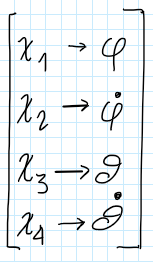

Inoltre, per definire il nostro sistema SIMO in forma matriciale, avremo bisogno del supporto delle matrici A-B-C-D. Per fare questo definiamo queste funzioni di supporto:

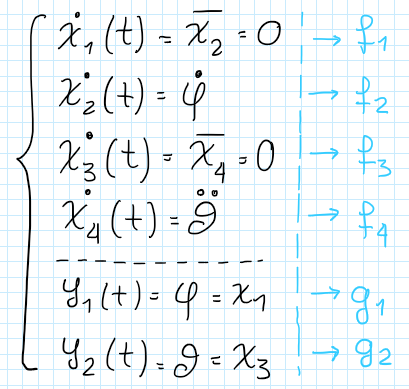

Da qui è quindi possibile poi ricavare le matrici A-B-C-D come segue:

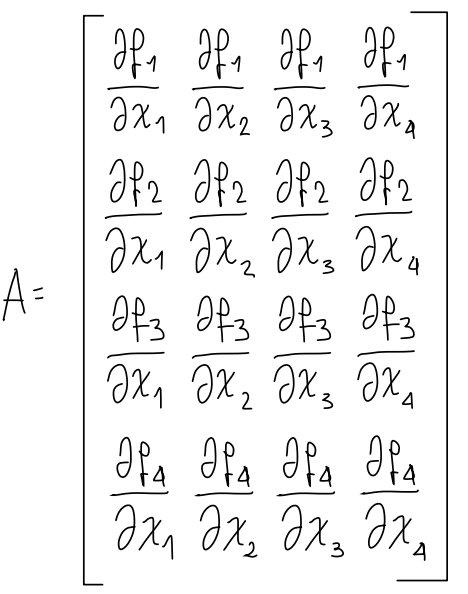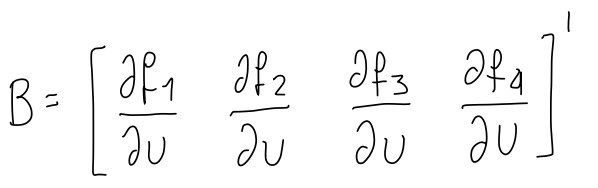

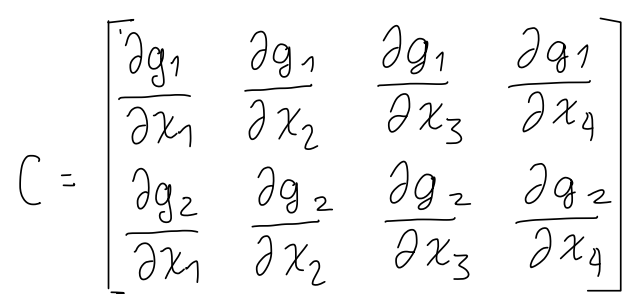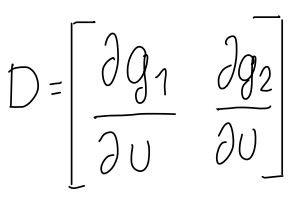

Dove le matrici A e B hanno nello specifico questa forma:

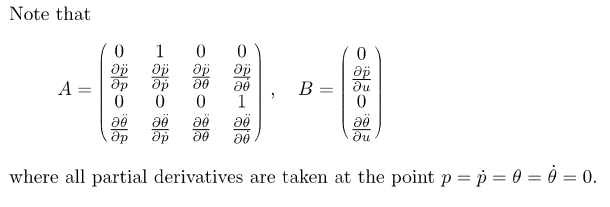

syms u;
theta2_differenziabile = subs(theta2,{phi,vel,theta,vel_ang,F},{q_1 q_1_p q_2 q_2_p u});
phi2_differenziabile = subs(phi2,{phi,vel,theta,vel_ang,F},{q_1 q_1_p q_2 q_2_p u});

%phi, phi_primo, theta, theta_primo, F (u = INPUT)
equilibrio = {0,0,0,0,0};

A11 = 0;
A12 = 1;
A13 = 0;
A14 = 0;
A21 = subs(diff(phi2_differenziabile,q_1),{q_1 q_1_p q_2 q_2_p u},equilibrio);
A22 = subs(diff(phi2_differenziabile,q_1_p),{q_1 q_1_p q_2 q_2_p u},equilibrio);
A23 = subs(diff(phi2_differenziabile,q_2),{q_1 q_1_p q_2 q_2_p u},equilibrio);
A24 = subs(diff(phi2_differenziabile,q_2_p),{q_1 q_1_p q_2 q_2_p u},equilibrio);
A31 = 0;
A32 = 0;
A33 = 0;
A34 = 1;
A41 = subs(diff(theta2_differenziabile,q_1),{q_1 q_1_p q_2 q_2_p u},equilibrio);
A42 = subs(diff(theta2_differenziabile,q_1_p),{q_1 q_1_p q_2 q_2_p u},equilibrio);
A43 = subs(diff(theta2_differenziabile,q_2),{q_1 q_1_p q_2 q_2_p u},equilibrio);
A44 = subs(diff(theta2_differenziabile,q_2_p),{q_1 q_1_p q_2 q_2_p u},equilibrio);
A = [A11 A12 A13 A14;A21 A22 A23 A24;A31 A32 A33 A34; A41 A42 A43 A44]

$$A = \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ 0 & 0.00141\,b & -4.166 & 0\\ 0 & 0 & 0 & 1\\ 0 & -0.004025\,b & 11.89 & 0 \end{array}\right)$$


B11 = 0;
B21 = subs(diff(phi2_differenziabile,u),{q_1 q_1_p q_2 q_2_p u},equilibrio);
B31 = 0;
B41 = subs(diff(theta2_differenziabile,u),{q_1 q_1_p q_2 q_2_p u},equilibrio);
B = [B11;B21;B31;B41]

$$B = \left(\begin{array}{c} 0\\ 0.01829\\ 0\\ 0.1436 \end{array}\right)$$


% Uscita l'angolo
% C -> matrice [2 (2 output) x 4 (4 var di stato)] TODO --> spiegazione
C = [0,0,1,0]

C =      0     0     1     0


D = 0

D = 0


syms s G(s);
G = collect(simplify(C*(s*eye(4)-A)^(-1)*B+D))

$$G = \frac{-2.872e+8\,s+5.523e+5\,b}{-2.0e+9\,s^{3}+\left(2.82e+6\,b\right)\,s^{2}+2.378e+10\,s+5849.0\,b}$$

## SIMULAZIONE

b = 0.1;
% % % % % Passing from symbolic to real values
% % % % A_real = subs(A,b)
% % % % A_real = double(A_real);
% % % % B_real = double(B);
% % % % C_real = double(C);
% % % % D_real = double(D);
% % % % G_real = collect(simplify(C_real*(s*eye(4)-A_real)^(-1)*B_real+D_real))
% % % % 
% % % % % Coefficients of transfer function (check: seems not correct)
% % % % [num,den] = ss2tf(A_real,B_real,C_real,D_real)

A_real = subs(A,b);
G_real = collect(simplify(C*(s*eye(4)-A_real)^(-1)*B+D))

$$G\_real = \frac{2.872e+9\,s-5.523e+5}{2.0e+10\,s^{3}-2.82e+6\,s^{2}-2.378e+11\,s-5849.0}$$


[num, den] = numden(G_real);
coeffs_num = double(coeffs(num));
N1 = coeffs_num(2)

N1 = -2.8724e+09

N2 = coeffs_num(1)

N2 = 552300


coeffs_den = double(coeffs(den));
D1 = coeffs_den(4)

D1 = -2.0000e+10

D2 = coeffs_den(3)

D2 = 2820200

D3 = coeffs_den(2)

D3 = 2.3778e+11

D4 = coeffs_den(1)

D4 = 5849

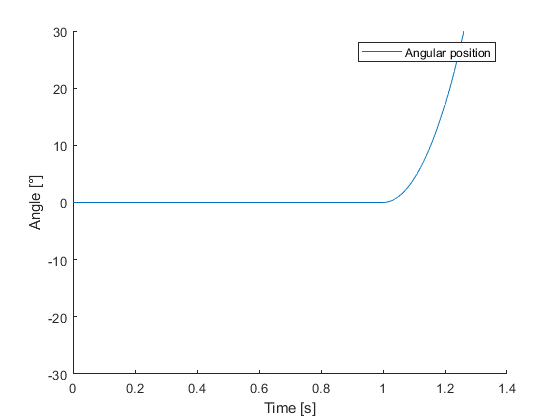


% D1 = -1.0e+10
% K1 = abs(D1);
% D2 = b*1.41e+7/K1
% D3 = 1.184e+11/K1
% D4 = 26620*b/K1
% N1 = -1.438e+9/K1
% N2 = 276e+6*b/K1
% D1 = D1/K1


t_end = 50;
Ts = 1/100;
control_on = 0;
k_p = -1;
sim  VABSim.slx 
clearvars no_control_sim;
no_control_sim(1,:) = sim_out;

figure
hold on
plot(tout, no_control_sim)
xlabel('Time [s]')
ylabel('Angle [°]')
ylim([-30 30])
legend('Angular position')

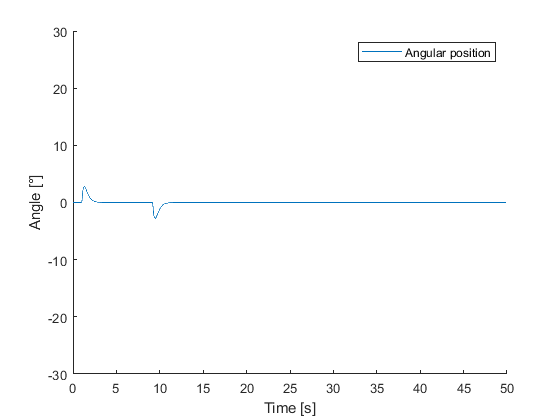

control_on = 1;
k_p = 10;

sim  VABSim 
clearvars control_sim;
control_sim(1,:) = sim_out;

figure
hold on
plot(tout, control_sim)
xlabel('Time [s]')
ylabel('Angle [°]')
ylim([-30 30])
legend('Angular position')